# ColorChecker Spectra of Different Displays

The purpose of the colorimetric evaluation is to evaluate how closely LightSim can reproduce color shades to be perceived by the human vision. Two colorimetric metrics were used -- $\Delta{u'v'}$ and $\Delta{E}_{00}$. The $\Delta{u'v'}$ metric is suitable for evaluating chromaticity difference only regardless their luminance. The $\Delta{E}_{00}$ metric is suitable for evaluating the perceived color difference between two color shades.

## Iterate displays

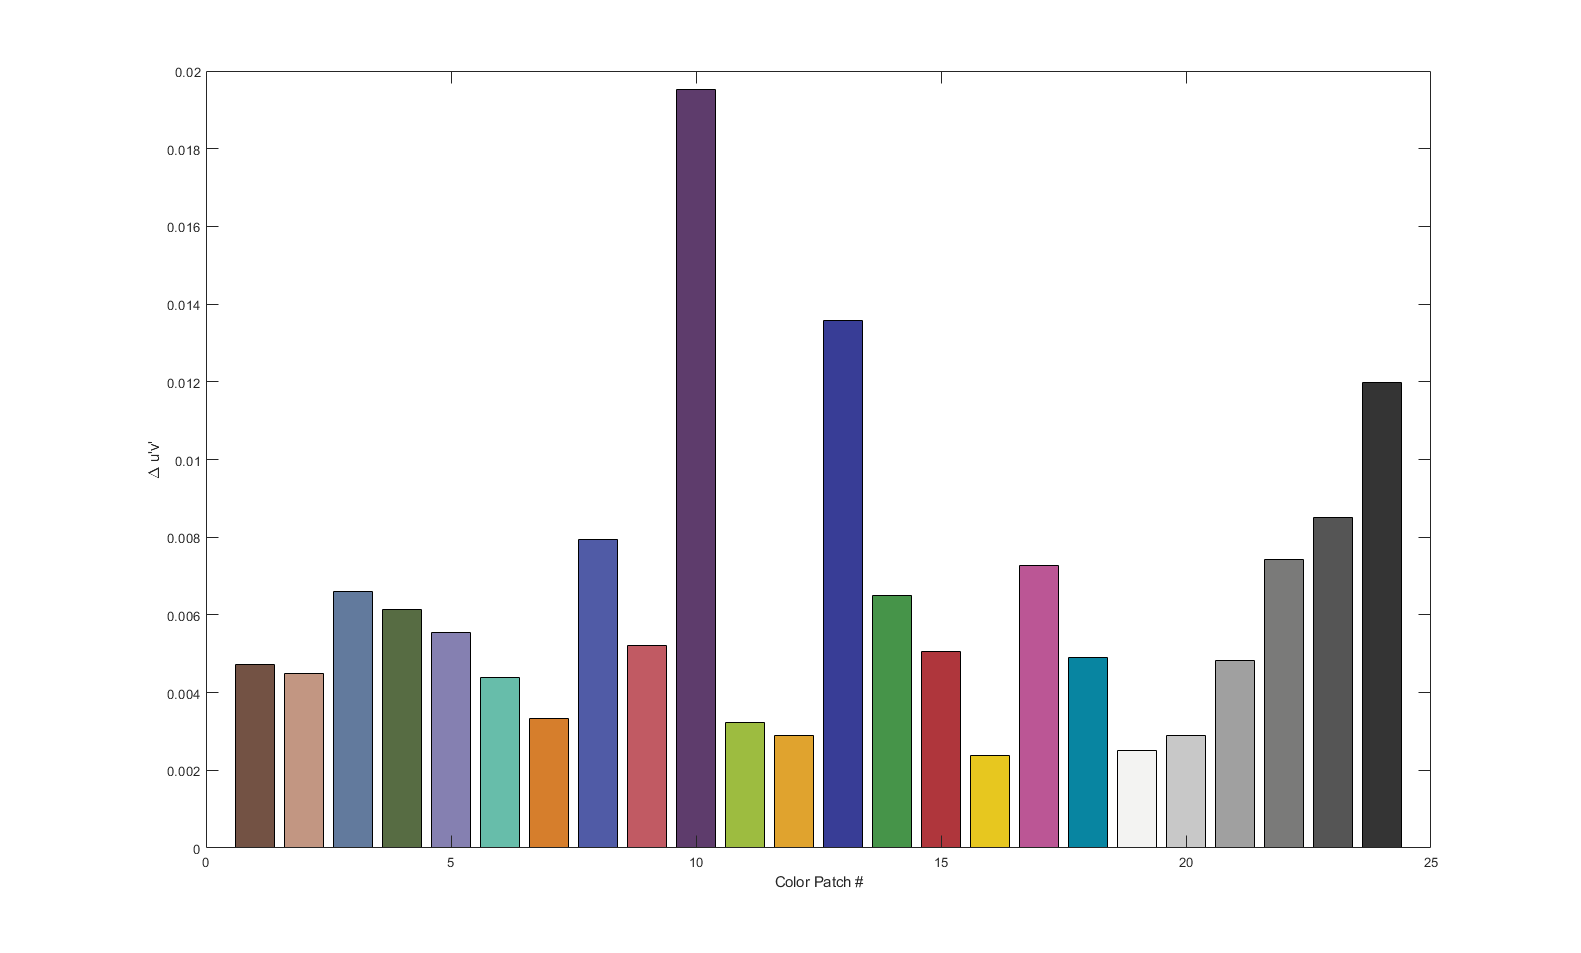

[dE_rift, duv_rift] = spectra_on_colorchecker('colorchecker_test_result_rift.mat','rift');

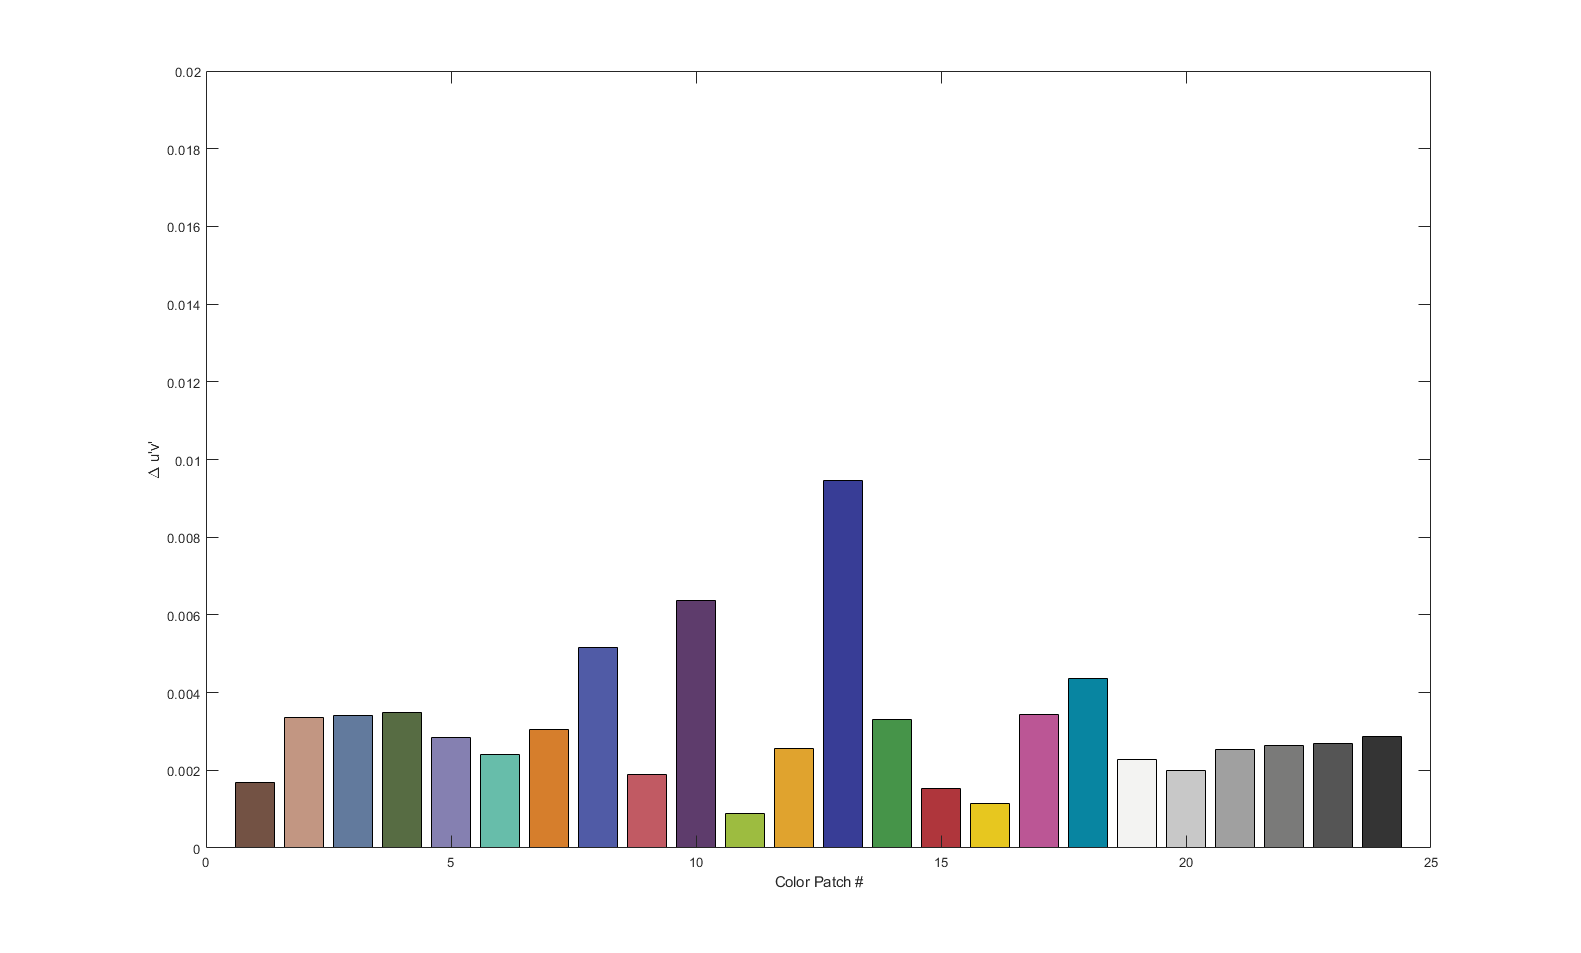

[dE_nec, duv_nec] = spectra_on_colorchecker('colorchecker_test_result_nec.mat','nec');

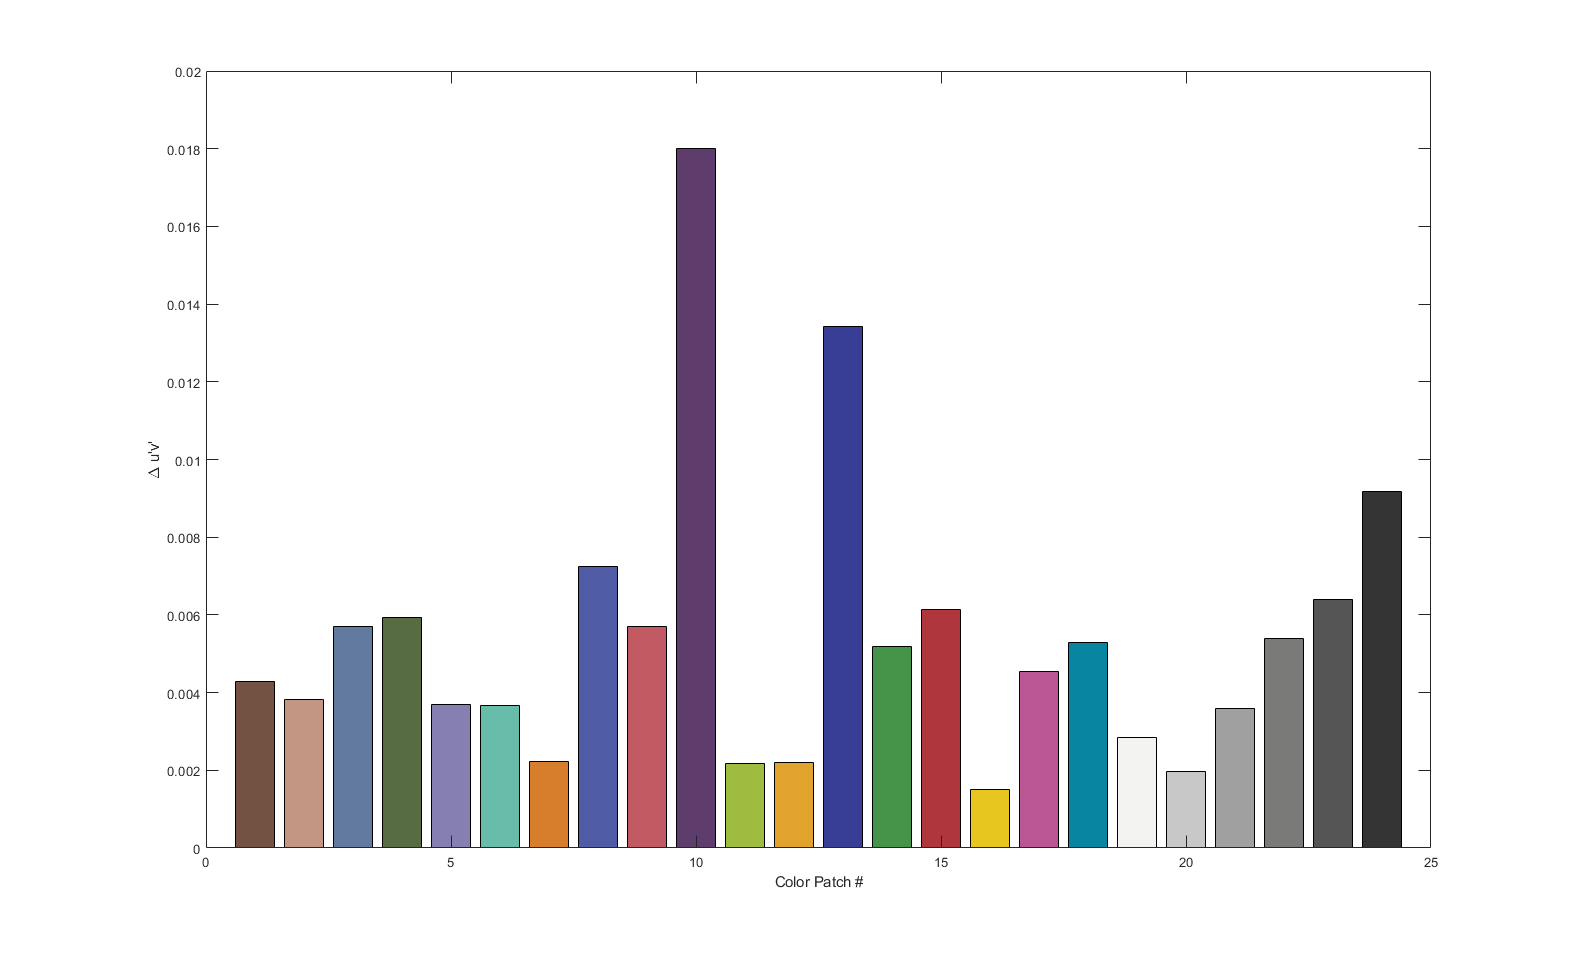

[dE_hp, duv_hp] = spectra_on_colorchecker('colorchecker_test_result_hp.mat','hp');

### dE boxplot

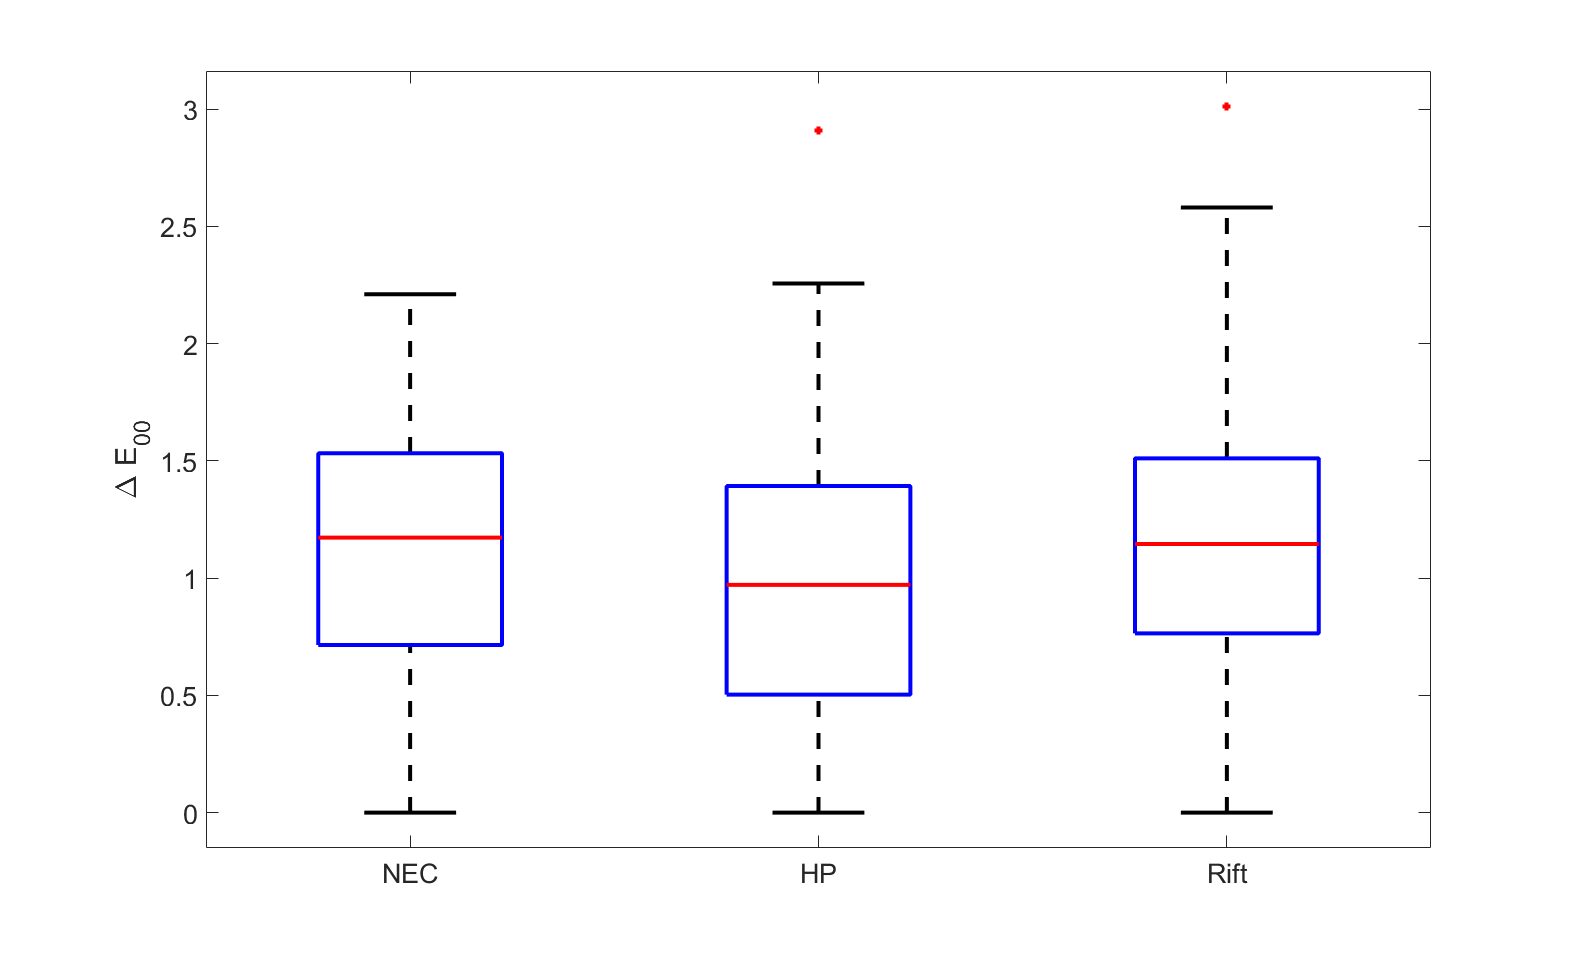

clf
dispname = {'NEC','HP','Rift'};
boxplot([dE_nec' dE_hp' dE_rift'],'Notch','off','Labels',dispname)
ylabel('\Delta E_{00}')
set(gca,'XTickLabel',dispname,'FontSize',20)

bx = findobj('Tag','boxplot');
set(bx.Children,'LineWidth',3)

saveas(gcf,'dE_boxplot.png')

### du'v' boxplot

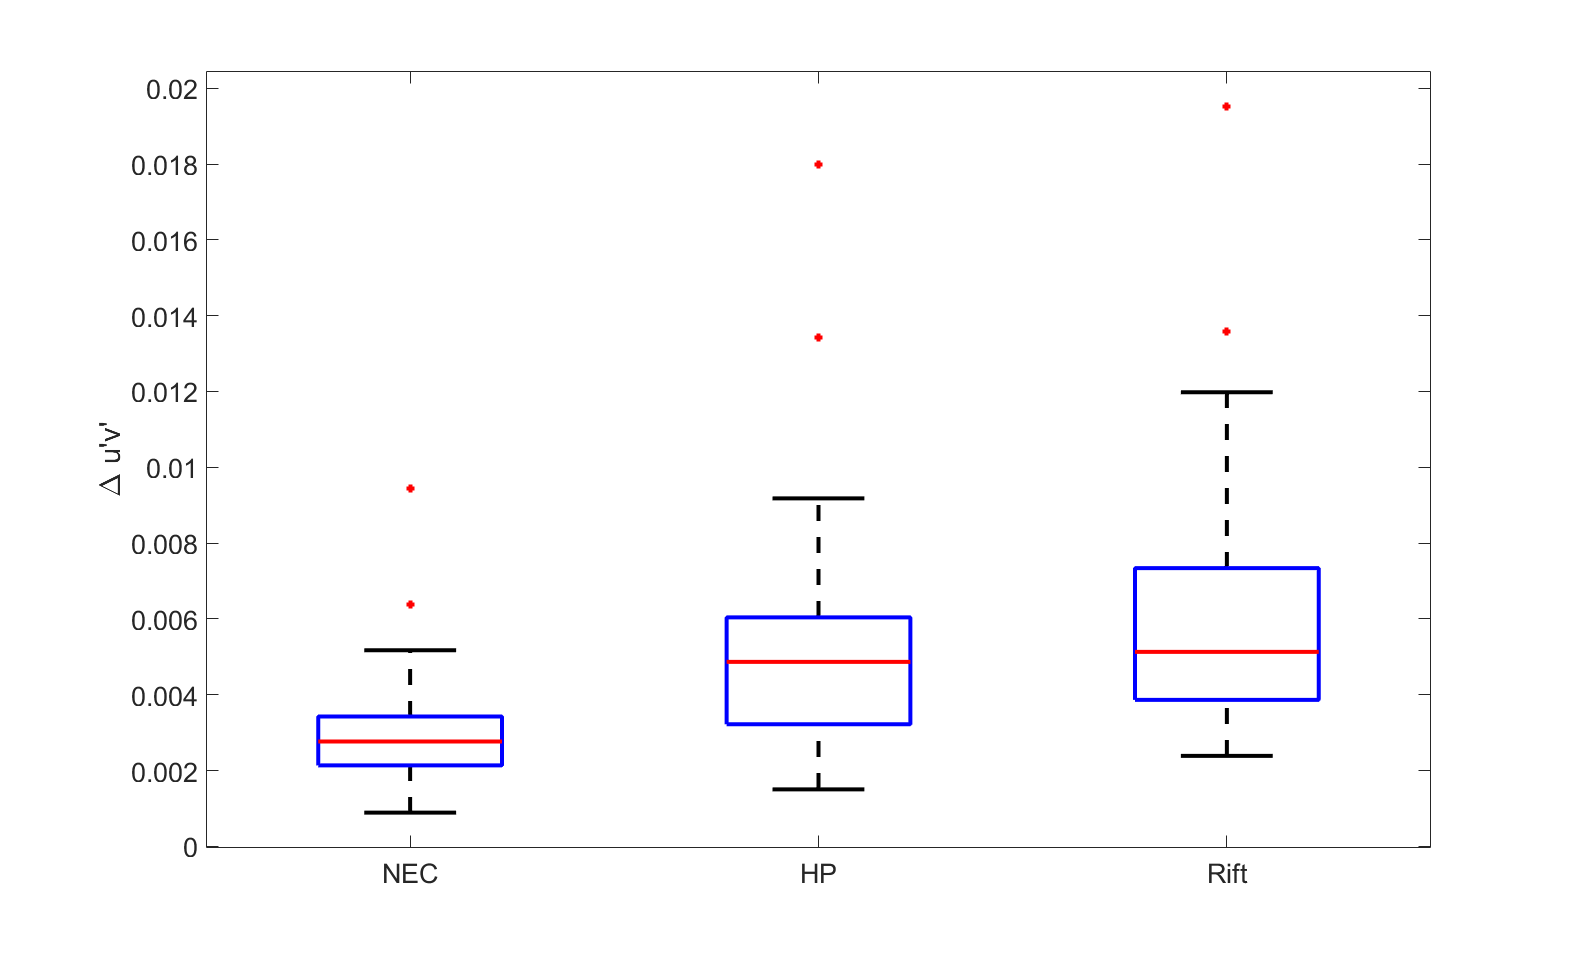

clf
dispname = {'NEC','HP','Rift'};
boxplot([duv_nec' duv_hp' duv_rift'],'Notch','off','Labels',dispname)
ylabel('\Delta u''v''')
set(gca,'XTickLabel',dispname,'FontSize',20)

bx = findobj('Tag','boxplot');
set(bx.Children,'LineWidth',3)

saveas(gcf,'duv_boxplot.png')

## The main function here

function [dE, duv] = spectra_on_colorchecker (fn_in,fn_out)

load(fn_in,'spd_ol490_24','spd_disp_24')

%
% reduce from 401 to 41
%
spec_ol490_24 = zeros(24,41);
for i = 1:24
    s = spd_ol490_24{i};
    s = s(1:10:end);
    spec_ol490_24(i,:) = s;
end

% XYZ is 24x3
XYZ_ol490 = ColorConversionClass.spd2XYZ(spec_ol490_24');
LAB_ol490 = ColorConversionClass.XYZ2lab(XYZ_ol490,XYZ_ol490(19,:));

%
% reduce from 401 to 41
%
spec_disp_24 = zeros(24,41);
for i = 1:24
    s = spd_disp_24{i};
    s = s(1:10:end);
    spec_disp_24(i,:) = s;
end

% XYZ is 24x3
XYZ_disp = ColorConversionClass.spd2XYZ(spec_disp_24');
LAB_disp = ColorConversionClass.XYZ2lab(XYZ_disp,XYZ_disp(19,:));


### Calculate dE


[dE00 dE94 dEab] = ColorConversionClass.LAB2dE(LAB_disp',LAB_ol490');
dE = dE00;


### Calculate du'v'

% calculate the u'v'
duv = zeros(1,24);
for i = 1:24
    duv(1,i) = ColorConversionClass.spd2duv(spec_ol490_24(i,:)',spec_disp_24(i,:)');
end

### Do work

generate_spectrum_plots (spd_disp_24, spd_ol490_24, fn_out);
generate_dE_bar_charts (dE, fn_out);
generate_duv_bar_charts (duv, fn_out)

end

### Generate the duv bar charts


function generate_duv_bar_charts (duv, fn_out)

colorchecker = [
    115 82  68;
    194 150 130;
    98  122 157;
    87  108 67;
    133 128 177;
    103 189 170;

    214 126 44;
    80  91  166;
    193 90  99;
    94  60  108;
    157 188 64;
    224 163 46;

    56  61  150;
    70  148 73;
    175 54  60;
    231 199 31;
    187 86  149;
    8   133 161;

    243 243 242;
    200 200 200;
    160 160 160;
    122 122 121;
    85  85  85;
    52  52  52
    ];

clf

hbar = bar(duv,'FaceColor','flat');
xlabel('Color Patch #')
ylabel('\Delta u''v''')

for i=1:24
    hbar.CData(i,:) = colorchecker(i,:)/255;
end
axis([0 25 0 .02])

fn = sprintf('duv_bar_%s.png',fn_out);
saveas(gcf,fn)

end

### Generate the dE bar charts


function generate_dE_bar_charts (dE, fn_out)

colorchecker = [
    115 82  68;
    194 150 130;
    98  122 157;
    87  108 67;
    133 128 177;
    103 189 170;

    214 126 44;
    80  91  166;
    193 90  99;
    94  60  108;
    157 188 64;
    224 163 46;

    56  61  150;
    70  148 73;
    175 54  60;
    231 199 31;
    187 86  149;
    8   133 161;

    243 243 242;
    200 200 200;
    160 160 160;
    122 122 121;
    85  85  85;
    52  52  52
    ];

clf

hbar = bar(dE,'FaceColor','flat');
xlabel('Color Patch #')
ylabel('\Delta E_{00}')

for i=1:24
    hbar.CData(i,:) = colorchecker(i,:)/255;
end
axis([0 25 0 4])

fn = sprintf('dE_bar_%s.png',fn_out);
saveas(gcf,fn)
end

### Generate the spectrum plots

function generate_spectrum_plots (spd_disp_24, spd_ol490_24, fn_out)

colorchecker = [
    115 82  68;
    194 150 130;
    98  122 157;
    87  108 67;
    133 128 177;
    103 189 170;

    214 126 44;
    80  91  166;
    193 90  99;
    94  60  108;
    157 188 64;
    224 163 46;

    56  61  150;
    70  148 73;
    175 54  60;
    231 199 31;
    187 86  149;
    8   133 161;

    243 243 242;
    200 200 200;
    160 160 160;
    122 122 121;
    85  85  85;
    52  52  52
    ];

clf
td = tiledlayout(4,6,'TileSpacing','compact');
hg = gcf;
set(hg,'Visible','on');

for idx = 1:24

    haxis = nexttile(idx);
    hold on

    plot(380:780,spd_ol490_24{idx},'m-')
    plot(380:780,spd_disp_24{idx},'c--')
    axis([380 780 0 2.5e-4])

    color_rgb = [0 0.5 1];

    %    title(idx)
    yticklabels({});
    PlotBeautify(haxis)
    legend off

    % change the background color
    set(haxis,'Color',colorchecker(idx,:)/255);

    if idx < 19
        xticklabels({});
    end

    haxis.XAxis.FontSize = 14;

    yticklabels({});

    %     if mod(idx,6)==1
    %         ylabel('SPD');
    %     end

end

td.XLabel.String = 'Wavelength (nm)';
td.XLabel.FontSize = 20;

td.YLabel.String = 'SPD';
td.YLabel.FontSize = 20;

hg.Position = [97 134 1581 953];

fn = sprintf('spectra_on_colorchecker_%s.png',fn_out);
saveas(hg,fn)

end